# 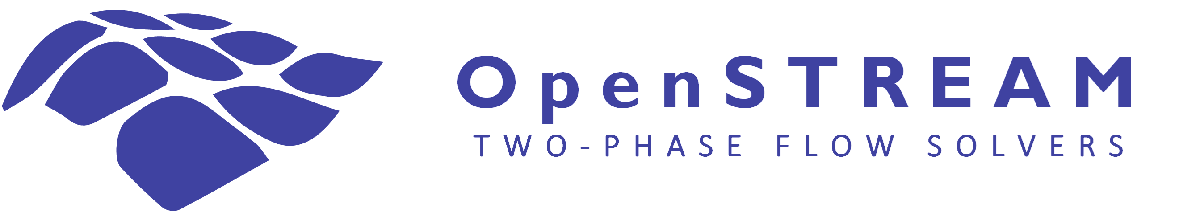

# Tutorial #1: OpenSTREAM Quick Start

Welcome to OpenSTREAM!

This tutorial runs one provided test case with each of the four OpenSTREAM solver frameworks. You will load the inputs, solve the case, create a few representative plots, and save the solver objects.

After completing this tutorial, you will be able to:

- Load an existing OpenSTREAM case.

- Run the mixture, two-fluid, three-field, and four-field solvers.

- Create basic axial plots.

- Save solver objects.

- Identify the next tutorial relevant to your work.

*Note: This tutorial is designed for use with output displayed inline (View > Output Inline) in the MATLAB Live Editor. Any animations are displayed in separate pop-up figure windows and can be played continuously or inspected one stored time step at a time. Animations and their controls are not preserved in static Markdown, HTML, or PDF exports.*

**Important**

*The physical models and closure relations selected in this tutorial are used for educational and demonstration purposes. Their use does not imply that they are appropriate, recommended, or validated for the simulated conditions. The calculated results should therefore be interpreted as illustrations of the solver framework and its capabilities, rather than as validated predictions. Before applying OpenSTREAM to a technical study, assess the assumptions, applicability range, and validation basis of every selected model.*

## Test case

The selected geometry consists of a 3.5 m uniformly heated vertical tube with an inner diameter of 8.8 mm, followed by a 2 m adiabatic section with the same diameter. The same case is used with all four solver frameworks so that their different field representations can be compared directly.

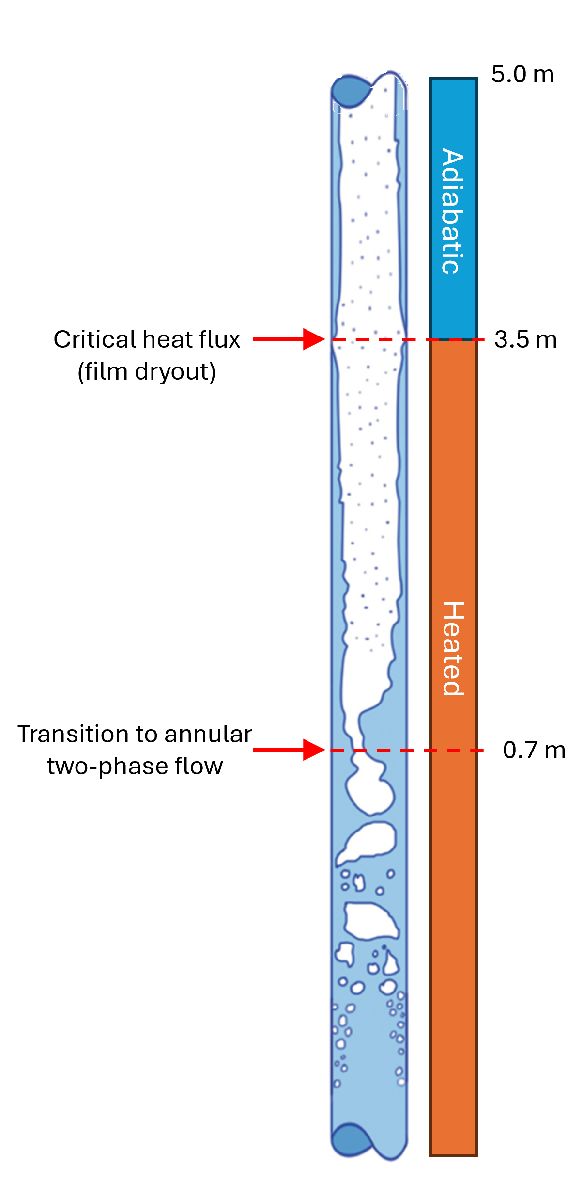

## Set up OpenSTREAM

Clear existing variables from the workspace.

clearvars

When this tutorial is run directly from the tutorials folder, the OpenSTREAM root directory is one level above the current folder.

osp = './..';
addpath(osp);

Import the input and solver packages.

import Inputs.*
import Solvers.*

## Load the example case

OpenSTREAM cases are defined by physical-model, numerical-option, geometry, and boundary-condition inputs. This tutorial uses input sets already provided with the repository.

Tutorial 6 explains the input system and reproducible case construction in detail.

Warning output is temporarily suppressed to keep the Quick Start concise. During model development, leaving warnings enabled is recommended.

warning off
% Construct the input set
inputSet = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL1', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');

warning on

Each solver first obtains a steady-state solution through pseudo-time advancement. Progress is displayed in the MATLAB Command Window.

Tutorial 7 explains point iterations, temporal convergence, solver states, and troubleshooting.

## Mixture solver

The mixture solver represents the flow through mixture quantities and derives liquid and vapor quantities from the selected mixture models.

import Solvers.Mixture.*

% Construct the mixture solver object and solve the flow field.
mixSolver = MixtureSolver(inputSet);
mixSolver.solve();

% Plot mass flow rates and vapor ratios.
mixSolver.plotz( ...
    'display', {'W','VR'}, ...
    'arrangement', 'horizontal', ...
    'resize', 1);

% Display a compact set of outlet results.
outletResults = table( ...
    mixSolver.Z(end), ...
    mixSolver.mixture.X(end), ...
    mixSolver.mixture.VF(end), ...
    'VariableNames', ...
    {'Elevation_m','VaporMassQuality','VoidFraction'});

disp(outletResults)

Tutorial 2 focuses on the mixture solver capabilities.

## Two-fluid solver

The two-fluid solver calculates separate liquid and vapor mass flow rates, velocities, and enthalpies. It requires a solved mixture solution for initialization and pressure-gradient information, so the previously solved mixture object is reused.

import Solvers.TwoFluid.*

% Construct the two-fluid solver object and solve the flow fields.
twfSolver = TwoFluidSolver(inputSet, mixSolver);
twfSolver.solve();

% Plot phase mass flow rates and velocities.
twfSolver.plotz( ...
    'display', {'W','U'}, ...
    'arrangement', 'horizontal', ...
    'resize', 1);

Tutorial 3 focuses on the two-fluid solver capabilities.

## Three-field solver

In the annular-flow region, the three-field solver divides the liquid between a wall-film field and an entrained-droplet field. The mixture solution supplies initialization and pressure-gradient information.

import Solvers.ThreeField.*

% Construct the three-field solver object and solve the flow fields.
tfSolver = ThreeFieldSolver(inputSet, mixSolver);
tfSolver.solve();

% Plot field mass flow rates and velocities.
tfSolver.plotz( ...
    'display', {'W','U'}, ...
    'arrangement', 'horizontal', ...
    'resize', 1);

Tutorial 4 focuses on the three-field solver capabilities.

## Four-field solver

The four-field solver further divides the liquid film into base-film and disturbance-wave fields and calculates wave-related quantities.

import Solvers.FourField.*

% Construct the four-field solver object and solve the flow fields.
ffSolver = FourFieldSolver(inputSet, mixSolver);
ffSolver.solve();

% Plot field mass flow rates and disturbance-wave frequency.
ffSolver.plotz( ...
    'display', {'W','FREQUENCY'}, ...
    'arrangement', 'horizontal', ...
    'resize', 1);

Tutorial 5 focuses on the four-field solver capabilities.

## Save the solver objects

Each solver object contains its inputs, solution fields, and associated session information. Save the objects if you want to reload and post-process them without repeating the calculations.

mixSolver.save('name','mixSolver','showpath',false);
twfSolver.save('name','twfSolver','showpath',false);
tfSolver.save('name','tfSolver','showpath',false);
ffSolver.save('name','ffSolver','showpath',false);

## Where to go next

Continue with the tutorial most relevant to your objective:

- Tutorial 2: Mixture solver capabilities

- Tutorial 3: Two-fluid solver capabilities

- Tutorial 4: Three-field solver capabilities

- Tutorial 5: Four-field solver capabilities

- Tutorial 6: Input files

- Tutorial 7: Numerical convergence and solver diagnostics

- Tutorial 8: Mesh and time-step sensitivity

- Tutorial 9: Advanced visualization and post-processing

## Summary

You loaded one OpenSTREAM case, ran all four solver frameworks, generated representative plots, inspected compact outlet results from the mixture solver, and saved the solver objects. The following tutorials develop each solver and the supporting workflows in greater detail.